%  n=2000, УОЗ=9
%  анализ "нормальных" циклов
%  а: добавить excel - файл с рабочими ИД "pressure_sens.xlsx" 
%  б: добавить excel - файл с ИД на прокрутке "pressure_sens_idle.xlsx" 
%  в: настроить параметры обработки 

if ~exist ("T_Mtrc_ExcelData")
  T_Mtrc_ExcelData=table2array(readtable("pressure_sens.xlsx"));
end
if ~exist ("T_Mtrc_ExcelData_idle")
  T_Mtrc_ExcelData_idle=table2array(readtable("pressure_sens_idle.xlsx"));
end

if length(T_Mtrc_ExcelData(:,1))~=length(T_Mtrc_ExcelData_idle(:,1))
    m = msgbox("размер матриц прокрутки и со сгоранием не равны");
end

P_Dbl_Pz=max(T_Mtrc_ExcelData(:,2:end),[],1);
P_Dbl_Pz_idle=max(T_Mtrc_ExcelData_idle(:,2:end),[],1);

P_Dbl_Pz_StDev=std(P_Dbl_Pz)

P_Dbl_Pz_StDev = 3.0360

P_Dbl_Pz_idle_StDev=std(P_Dbl_Pz_idle)

P_Dbl_Pz_idle_StDev = 0.3941

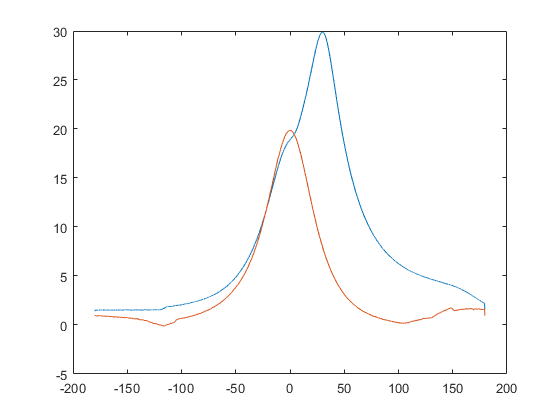


%осреднение индикаторных диаграмм:
A_Mtrx_DPKV=T_Mtrc_ExcelData(:,1);
T_Mtrx_Pressure=T_Mtrc_ExcelData(:,2:end);
T_Mtrx_Pressure_mean=mean(T_Mtrx_Pressure,2);
T_Mtrx_Pressure_idle=T_Mtrc_ExcelData_idle(:,2:end);
T_Mtrx_Pressure_idle_mean=mean(T_Mtrx_Pressure_idle,2);

plot(A_Mtrx_DPKV, T_Mtrx_Pressure_mean, A_Mtrx_DPKV, T_Mtrx_Pressure_idle_mean)


%среднее индикаторное давление
P_Dbl_Mtrx_DPKV_lngth=round(length(A_Mtrx_DPKV)/2+1)

P_Dbl_Mtrx_DPKV_lngth = 1801


P_Dbl_ComprStroke_Pi=trapz(A_Mtrx_DPKV(1:P_Dbl_Mtrx_DPKV_lngth),T_Mtrx_Pressure_mean(1:P_Dbl_Mtrx_DPKV_lngth))/400;
P_Dbl_PowerStroke_Pi=trapz(A_Mtrx_DPKV(P_Dbl_Mtrx_DPKV_lngth:end),T_Mtrx_Pressure_mean(P_Dbl_Mtrx_DPKV_lngth:end))/400;
P_Dbl_Pi=P_Dbl_PowerStroke_Pi-P_Dbl_ComprStroke_Pi

P_Dbl_Pi = 3.0887


P_Dbl_ComprStroke_Pi_idle=trapz(A_Mtrx_DPKV(1:P_Dbl_Mtrx_DPKV_lngth),T_Mtrx_Pressure_idle_mean(1:P_Dbl_Mtrx_DPKV_lngth))/400;
P_Dbl_PowerStroke_Pi_idle=trapz(A_Mtrx_DPKV(P_Dbl_Mtrx_DPKV_lngth:end),T_Mtrx_Pressure_idle_mean(P_Dbl_Mtrx_DPKV_lngth:end))/400;
P_Dbl_Pi_idle=P_Dbl_PowerStroke_Pi_idle-P_Dbl_ComprStroke_Pi_idle

P_Dbl_Pi_idle = -0.0162